cd(fileparts(matlab.desktop.editor.getActiveFilename))
close all; clearvars; clc

stroke_participant_list = ["P05", "P06", "P07", "P08", "P09"];
healthy_participant_list = ["P10", "P11", "P12", "P13", "P14"];
data_path = "D:\FRM\co-adaptive-learning";

participant_array = Participant.empty();
p_insertion_idx = 1;
dir_list = dir(data_path);

for i = 1:length(dir_list)
    dir_item = dir_list(i).name;
    if or(dir_item==".", dir_item=="..")
        continue
    end
    % Create participant object
    participant_id = regexprep(upper(dir_item), '-','')
    item_path = join([data_path, dir_item], "\");
    if ismember(participant_id, stroke_participant_list)
        p_handle = StrokeParticipant(item_path, participant_id);
    elseif ismember(participant_id, healthy_participant_list)
        p_handle = HealthyParticipant(item_path, participant_id);
    else
        error("Condition of participant %s is undefined", participant_id)
    end

    % Store participant object in particpant array
    participant_array(p_insertion_idx) = p_handle;
    p_insertion_idx = p_insertion_idx + 1;
end

participant_id = 'P05'

Loading Training File: D:\FRM\co-adaptive-learning\p-05\paretic\ml\TrainingData_20230308-190608_190709.kdf
Training Kalman: 01 iteration(s)
Training Kalman: 02 iteration(s)
Training Kalman: 03 iteration(s)
Training Kalman: 04 iteration(s)
Training Kalman: 05 iteration(s)
Training Kalman: 06 iteration(s)
Training Kalman: 07 iteration(s)
Training Kalman: 08 iteration(s)
Training Kalman: 09 iteration(s)
Training Kalman: 10 iteration(s)
Loading Task File: D:\FRM\co-adaptive-learning\p-05\paretic\hl\TaskData_20230308-192607.kdf
Loading Task File: D:\FRM\co-adaptive-learning\p-05\paretic\cl\TaskData_20230308-191220.kdf
Loading Training File: D:\FRM\co-adaptive-learning\p-05\nonparetic\ml\TrainingData_20230308-181939_182333.kdf
Training Kalman: 01 iteration(s)
Training Kalman: 02 iteration(s)
Training Kalman: 03 iteration(s)
Training Kalman: 04 iteration(s)
Training Kalman: 05 iteration(s)
Training Kalman: 06 iteration(s)
Training Kalman: 07 iteration(s)
Training Kalman: 08 iteration(s)
Train

participant_id = 'P06'

Loading Training File: D:\FRM\co-adaptive-learning\p-06\paretic\ml\TrainingData_20230310-173032_173243.kdf
Training Kalman: 01 iteration(s)
Training Kalman: 02 iteration(s)
Training Kalman: 03 iteration(s)
Training Kalman: 04 iteration(s)
Training Kalman: 05 iteration(s)
Training Kalman: 06 iteration(s)
Training Kalman: 07 iteration(s)
Training Kalman: 08 iteration(s)
Training Kalman: 09 iteration(s)
Training Kalman: 10 iteration(s)
Loading Task File: D:\FRM\co-adaptive-learning\p-06\paretic\hl\TaskData_20230310-175819.kdf
Loading Task File: D:\FRM\co-adaptive-learning\p-06\paretic\cl\TaskData_20230310-173822.kdf
Loading Training File: D:\FRM\co-adaptive-learning\p-06\nonparetic\ml\TrainingData_20230310-164347_164805.kdf
Training Kalman: 01 iteration(s)
Training Kalman: 02 iteration(s)
Training Kalman: 03 iteration(s)
Training Kalman: 04 iteration(s)
Training Kalman: 05 iteration(s)
Training Kalman: 06 iteration(s)
Training Kalman: 07 iteration(s)
Training Kalman: 08 iteration(s)
Train

participant_id = 'P07'

Loading Training File: D:\FRM\co-adaptive-learning\p-07\paretic\ml\TrainingData_20230313-125712_130002.kdf
Training Kalman: 01 iteration(s)
Training Kalman: 02 iteration(s)
Training Kalman: 03 iteration(s)
Training Kalman: 04 iteration(s)
Training Kalman: 05 iteration(s)
Training Kalman: 06 iteration(s)
Training Kalman: 07 iteration(s)
Training Kalman: 08 iteration(s)
Training Kalman: 09 iteration(s)
Training Kalman: 10 iteration(s)
Loading Task File: D:\FRM\co-adaptive-learning\p-07\paretic\hl\TaskData_20230313-132619.kdf
Loading Task File: D:\FRM\co-adaptive-learning\p-07\paretic\cl\TaskData_20230313-130615.kdf
Loading Training File: D:\FRM\co-adaptive-learning\p-07\nonparetic\ml\TrainingData_20230313-120910_121228.kdf
Training Kalman: 01 iteration(s)
Training Kalman: 02 iteration(s)
Training Kalman: 03 iteration(s)
Training Kalman: 04 iteration(s)
Training Kalman: 05 iteration(s)
Training Kalman: 06 iteration(s)
Training Kalman: 07 iteration(s)
Training Kalman: 08 iteration(s)
Train

participant_id = 'P08'

Loading Training File: D:\FRM\co-adaptive-learning\p-08\paretic\ml\TrainingData_20230504-152730_153034.kdf
Training Kalman: 01 iteration(s)
Training Kalman: 02 iteration(s)
Training Kalman: 03 iteration(s)
Training Kalman: 04 iteration(s)
Training Kalman: 05 iteration(s)
Training Kalman: 06 iteration(s)
Training Kalman: 07 iteration(s)
Training Kalman: 08 iteration(s)
Training Kalman: 09 iteration(s)
Training Kalman: 10 iteration(s)
Loading Task File: D:\FRM\co-adaptive-learning\p-08\paretic\hl\TaskData_20230504-155210.kdf
Loading Task File: D:\FRM\co-adaptive-learning\p-08\paretic\cl\TaskData_20230504-153706.kdf
Loading Training File: D:\FRM\co-adaptive-learning\p-08\nonparetic\ml\TrainingData_20230504-141815_142323.kdf
Training Kalman: 01 iteration(s)
Training Kalman: 02 iteration(s)
Training Kalman: 03 iteration(s)
Training Kalman: 04 iteration(s)
Training Kalman: 05 iteration(s)
Training Kalman: 06 iteration(s)
Training Kalman: 07 iteration(s)
Training Kalman: 08 iteration(s)
Train

participant_id = 'P09'

Loading Training File: D:\FRM\co-adaptive-learning\p-09\paretic\ml\TrainingData_20230517-140848_141004.kdf
Training Kalman: 01 iteration(s)
Training Kalman: 02 iteration(s)
Training Kalman: 03 iteration(s)
Training Kalman: 04 iteration(s)
Training Kalman: 05 iteration(s)
Training Kalman: 06 iteration(s)
Training Kalman: 07 iteration(s)
Training Kalman: 08 iteration(s)
Training Kalman: 09 iteration(s)
Training Kalman: 10 iteration(s)
Loading Task File: D:\FRM\co-adaptive-learning\p-09\paretic\hl\TaskData_20230517-143754.kdf
Loading Task File: D:\FRM\co-adaptive-learning\p-09\paretic\cl\TaskData_20230517-142321.kdf
Loading Training File: D:\FRM\co-adaptive-learning\p-09\nonparetic\ml\TrainingData_20230517-132109_132556.kdf
Training Kalman: 01 iteration(s)
Training Kalman: 02 iteration(s)
Training Kalman: 03 iteration(s)
Training Kalman: 04 iteration(s)
Training Kalman: 05 iteration(s)
Training Kalman: 06 iteration(s)
Training Kalman: 07 iteration(s)
Training Kalman: 08 iteration(s)
Train

participant_id = 'P10'

Loading Training File: D:\FRM\co-adaptive-learning\p-10\healthy\ml\TrainingData_20231003-164321_164439.kdf
Training Kalman: 01 iteration(s)
Training Kalman: 02 iteration(s)
Training Kalman: 03 iteration(s)
Training Kalman: 04 iteration(s)
Training Kalman: 05 iteration(s)
Training Kalman: 06 iteration(s)
Training Kalman: 07 iteration(s)
Training Kalman: 08 iteration(s)
Training Kalman: 09 iteration(s)
Training Kalman: 10 iteration(s)
Loading Task File: D:\FRM\co-adaptive-learning\p-10\healthy\hl\TaskData_20231003-171017.kdf
Loading Task File: D:\FRM\co-adaptive-learning\p-10\healthy\cl\TaskData_20231003-165053.kdf


participant_id = 'P11'

Loading Training File: D:\FRM\co-adaptive-learning\p-11\healthy\ml\TrainingData_20231017-151637_152145.kdf
Training Kalman: 01 iteration(s)
Training Kalman: 02 iteration(s)
Training Kalman: 03 iteration(s)
Training Kalman: 04 iteration(s)
Training Kalman: 05 iteration(s)
Training Kalman: 06 iteration(s)
Training Kalman: 07 iteration(s)
Training Kalman: 08 iteration(s)
Training Kalman: 09 iteration(s)
Training Kalman: 10 iteration(s)
Loading Task File: D:\FRM\co-adaptive-learning\p-11\healthy\hl\TaskData_20231017-155736.kdf
Loading Task File: D:\FRM\co-adaptive-learning\p-11\healthy\cl\TaskData_20231017-154101.kdf


participant_id = 'P12'

Loading Training File: D:\FRM\co-adaptive-learning\p-12\healthy\ml\TrainingData_20231107-143724_145332.kdf
Training Kalman: 01 iteration(s)
Training Kalman: 02 iteration(s)
Training Kalman: 03 iteration(s)
Training Kalman: 04 iteration(s)
Training Kalman: 05 iteration(s)
Training Kalman: 06 iteration(s)
Training Kalman: 07 iteration(s)
Training Kalman: 08 iteration(s)
Training Kalman: 09 iteration(s)
Training Kalman: 10 iteration(s)
Loading Task File: D:\FRM\co-adaptive-learning\p-12\healthy\hl\TaskData_20231107-152055.kdf
Loading Task File: D:\FRM\co-adaptive-learning\p-12\healthy\cl\TaskData_20231107-150053.kdf


participant_id = 'P13'

Loading Training File: D:\FRM\co-adaptive-learning\p-13\healthy\ml\TrainingData_20231115-144110_144742.kdf
Training Kalman: 01 iteration(s)
Training Kalman: 02 iteration(s)
Training Kalman: 03 iteration(s)
Training Kalman: 04 iteration(s)
Training Kalman: 05 iteration(s)
Training Kalman: 06 iteration(s)
Training Kalman: 07 iteration(s)
Training Kalman: 08 iteration(s)
Training Kalman: 09 iteration(s)
Training Kalman: 10 iteration(s)
Loading Task File: D:\FRM\co-adaptive-learning\p-13\healthy\hl\TaskData_20231115-151034.kdf
Loading Task File: D:\FRM\co-adaptive-learning\p-13\healthy\cl\TaskData_20231115-145518.kdf


participant_id = 'P14'

Loading Training File: D:\FRM\co-adaptive-learning\p-14\healthy\ml\TrainingData_20231121-145811_150219.kdf
Training Kalman: 01 iteration(s)
Training Kalman: 02 iteration(s)
Training Kalman: 03 iteration(s)
Training Kalman: 04 iteration(s)
Training Kalman: 05 iteration(s)
Training Kalman: 06 iteration(s)
Training Kalman: 07 iteration(s)
Training Kalman: 08 iteration(s)
Training Kalman: 09 iteration(s)
Training Kalman: 10 iteration(s)
Loading Task File: D:\FRM\co-adaptive-learning\p-14\healthy\hl\TaskData_20231121-152337.kdf
Loading Task File: D:\FRM\co-adaptive-learning\p-14\healthy\cl\TaskData_20231121-150818.kdf


% Prune and label participant data
for i =1:numel(participant_array)

Error using save
Unable to save file 'C:\Users\Fredi Mino\Documents\research-projects\co-adaptive-learning\temp-data\participant_list_unpruned.mat'. The file could not be closed, and might now be corrupt.

    p_handle = participant_array(i);
    disp(p_handle.participant_id);
    for j = 1:numEntries(p_handle.cond_dict)
        cond_keys = keys(p_handle.cond_dict);
        cond_vals = values(p_handle.cond_dict);
        cond  = cond_vals(j);
        for k=1:numEntries(cond.task_dict)
            task_keys = keys(cond.task_dict);
            task_vals = values(cond.task_dict);
            task = task_vals{k};
            task_type = task_keys(k);
            try
                pruned_ttbl = frm_deng_utils.prune_timetable(task.data_ttbl, task_type);
            catch
                disp([p_handle.participant_id, cond_keys(j), task_type])
            end
            if and(p_handle.participant_id == "P06", and(cond_keys(j) == "par", task_keys(k) == "hl"))
                task.events_tbl = task.events_tbl(3:end,:);
            end
            if and(p_handle.participant_id == "P12", and(cond_keys(j) == "hlt", task_keys(k) == "ml"))
                task.events_tbl{23,"TargOnTS"} = task.data_ttbl{5936, "NIP Time"};
                task.events_tbl{24,"TargOnTS"} = task.data_ttbl{6275, "NIP Time"};
                task.events_tbl{26,"TargOnTS"} = task.data_ttbl{6734, "NIP Time"};
                task.events_tbl{29,"TargOnTS"} = task.data_ttbl{7533, "NIP Time"};
                task.events_tbl{23,"TrialTS"} = task.data_ttbl{6274, "NIP Time"};
                task.events_tbl{25,"TrialTS"} = task.data_ttbl{6733, "NIP Time"};
                task.events_tbl{28,"TrialTS"} = task.data_ttbl{7532, "NIP Time"};
                task.events_tbl{29,"TrialTS"} = task.data_ttbl{7872, "NIP Time"};
                task.events_tbl{30,"TrialTS"} = task.data_ttbl{7992, "NIP Time"};
            end
            task.data_ttbl = frm_deng_utils.label_timetable(pruned_ttbl, task.events_tbl, task_type);
        end
    end
end

P05
P06
P07
P08
P09
P10
P11
P12
P13
P14


save("..\..\temp-data\participant_list", "participant_array")

P06 - paretic- human learning - remove first two events

p_handle = participant_array(10)

p_handle =   HealthyParticipant with properties:

    participant_id: 'P14'
         cond_dict: dictionary (string ⟼ Condition) with 1 entry


p_cond = "hlt";
p_task = "ml";
task_data = p_handle.cond_dict(p_cond).task_dict{p_task}.data_ttbl;
task_events = p_handle.cond_dict(p_cond).task_dict{p_task}.events_tbl;
if (p_handle.participant_id == "P12")
    task_events{23,"TargOnTS"} = task_data{5936, "NIP Time"};
    task_events{24,"TargOnTS"} = task_data{6275, "NIP Time"};
    task_events{26,"TargOnTS"} = task_data{6734, "NIP Time"};
    task_events{29,"TargOnTS"} = task_data{7533, "NIP Time"};
    task_events{23,"TrialTS"} = task_data{6274, "NIP Time"};
    task_events{25,"TrialTS"} = task_data{6733, "NIP Time"};
    task_events{28,"TrialTS"} = task_data{7532, "NIP Time"};
    task_events{29,"TrialTS"} = task_data{7872, "NIP Time"};
    task_events{30,"TrialTS"} = task_data{7992, "NIP Time"};
end
if iscell(task_events{:,"TargOnTS"})
    event_starts = ismember(task_data{:,"NIP Time"}, cell2mat(task_events{:,"TargOnTS"}));
else
    event_starts = ismember(task_data{:,"NIP Time"}, task_events{:,"TargOnTS"});
end
event_stops = ismember(task_data{:,"NIP Time"}, task_events{:,"TrialTS"});

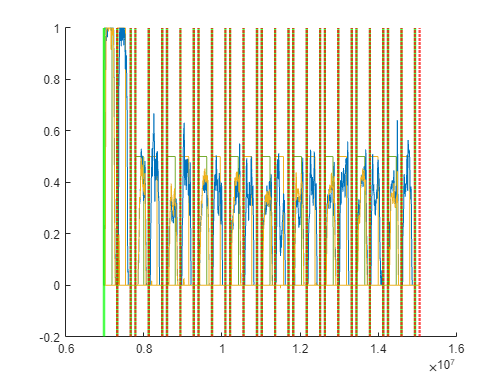

figure
hold on
plot(task_data.("NIP Time"), task_data.("Targets"))
plot(task_data.("NIP Time"), task_data.("Kalman 10"))
xline(task_data{event_starts, "NIP Time"}, 'LineWidth', 2, 'Color','g')
xline(task_data{event_stops, "NIP Time"}, 'LineWidth', 2, 'Color','r', 'LineStyle',':')
hold off

any(ismember(task_data{:,"NIP Time"}, task_events{30,"TrialTS"}))

find(task_data{:,"NIP Time"}>=task_events{30,"TrialTS"}, 1,"first")
task_data{7992, "NIP Time"}
task_events{30,"TrialTS"}